## Impact Simulation Analysis & Figure Generation

clc;
clear all;
%% =======================================================================
% POST-PROCESSING PIPELINE – Impact Simulation Analysis & Figure Generation
% Purpose:
%   - Load outputs from Monte Carlo impact simulations
%   - Compute fluxes, melt production, and atmospheric O₂ consumption
%   - Perform statistical aggregation (mean, std, percentiles)
%   - Integrate external datasets for comparison
%   - Produce all publication-ready figures for results section
% =======================================================================

### Load Global Variables

sim_count = 1000;       % Total number of simulation seeds available
num_ensembles = 50;     % Maximum number of ensembles to analyze in one run
plot_output_type = 'image'; % Change to 'vector' for high def (will take longer)
resolution_scale = 300; % Change the resolution scale of each image.

% --- Determine how many ensembles to use ---
% If the total simulations available is less than 50, 
%   use all available simulations as ensembles.
% If there are 50 or more simulations available,
%   cap the number of ensembles at 50 for consistency/computational efficiency.
if sim_count < 50
    ensembles_to_use = sim_count;   % Use all available sims as ensembles
else
    ensembles_to_use = 50;          % Limit to 50 ensembles
end

%% Constants & time
earth_surface_area_km2 = 510.1e6;  % [km²]
t_Ma = 1:4500;
t_Ga = t_Ma / 1000;

### Figure S2: Impact Fluxes and Melt Production from Asteroids and Comets

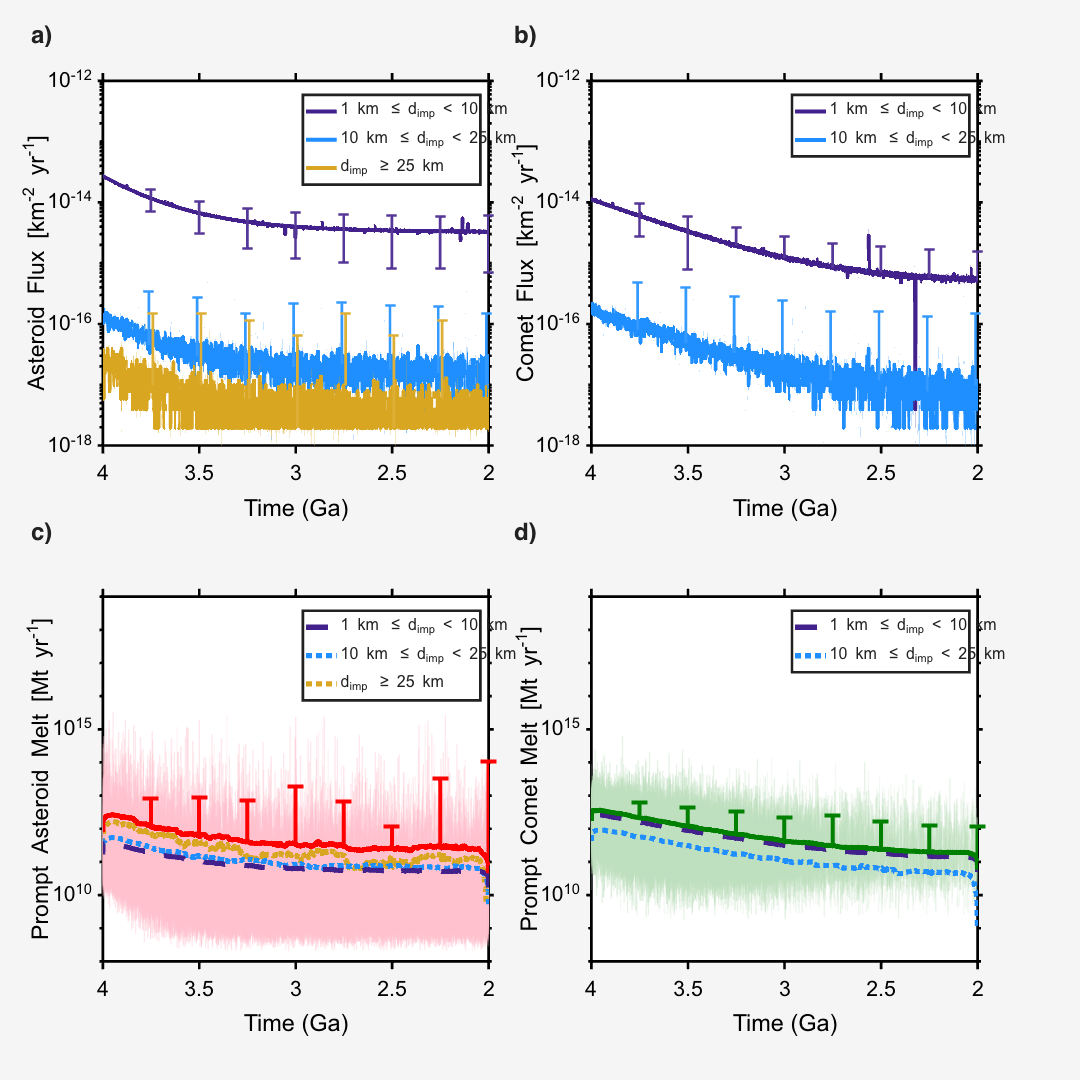

%% =======================================================================
% FIGURE S2 – Impact Fluxes and Melt Production from Asteroids and Comets
% Purpose:
%   - Load simulated asteroid and comet impact datasets
%   - Compute mean and standard deviation of fluxes (per km² per year)
%     for different size classes of impactors
%   - Plot four panels:
%       (a) Asteroid impact flux over time
%       (b) Comet impact flux over time
%       (c) Prompt asteroid melt production
%       (d) Prompt comet melt production
%   - Include ensemble spread, smoothed mean trends, and error bars
%   - Display geological time in Ga (billions of years ago) on reversed x-axis
% =======================================================================

%% Load data
fname = sprintf("post_proc_output/impact_count_1_10_25_%d_sims.mat", sim_count);
load(fname);

%% --- Normalize asteroid impact counts (per km² per timestep) ---
asteroids_1_to_10_km_flux  = asteroids_1_to_10_km   / earth_surface_area_km2 / 1e6;
asteroids_10_to_25_km_flux = asteroids_10_to_25_km  / earth_surface_area_km2 / 1e6;
asteroids_gt_25_km_flux    = asteroids_gt_25_km     / earth_surface_area_km2 / 1e6;

% Standard deviation across seeds
std_asteroids_1_to_10_km   = std(asteroids_1_to_10_km_flux,  0, 2);
std_asteroids_10_to_25_km  = std(asteroids_10_to_25_km_flux, 0, 2);
std_asteroids_gt_25_km     = std(asteroids_gt_25_km_flux,    0, 2);

%% --- Normalize comet impact counts (per km² per timestep) ---
comets_1_to_10_km_flux     = comets_1_to_10_km      / earth_surface_area_km2 / 1e6;
comets_10_to_25_km_flux    = comets_10_to_25_km     / earth_surface_area_km2 / 1e6;

% Standard deviation across seeds
std_comets_1_to_10_km      = std(comets_1_to_10_km_flux,     0, 2);
std_comets_10_to_25_km     = std(comets_10_to_25_km_flux,    0, 2);

%% Mean flux across seeds
mean_asteroids_1_to_10_km  = mean(asteroids_1_to_10_km_flux,  2);
mean_asteroids_10_to_25_km = mean(asteroids_10_to_25_km_flux, 2);
mean_asteroids_gt_25_km    = mean(asteroids_gt_25_km_flux,    2);

mean_comets_1_to_10_km     = mean(comets_1_to_10_km_flux,     2);
mean_comets_10_to_25_km    = mean(comets_10_to_25_km_flux,    2);

%% --- Figure & shared styling ---
figure('Units', 'pixels', 'Position', [100, 100, 1400, 1400]);
tiledlayout(2, 2, 'TileSpacing', 'loose', 'Padding', 'loose');

% Colors
purple = [0.26 0.13 0.55];
blue   = [0.12 0.56 1.00];
gold   = [0.85 0.65 0.13];
colors = {purple, blue, gold, 'k'};  % used later

% Faded colors for error bars
fade          = @(c, a) (1 - a) * c + a * [1 1 1];
purple_faint  = fade(purple, 0.1);
blue_faint    = fade(blue,   0.1);
gold_faint    = fade(gold,   0.1);

%% ------------------- (1) Asteroid Flux -------------------
nexttile;

sample_indices = 1:250:length(t_Ma);
t_sample       = t_Ma(sample_indices);

t_offset1 = t_sample;        % 1–10 km
t_offset2 = t_sample + 10;   % 10–25 km
t_offset3 = t_sample - 10;   % >25 km

line_thickness = 3;
cap_size       = 8;

% Mean flux lines
h_1to10 = plot(t_Ga, mean_asteroids_1_to_10_km,  'Color', purple, 'LineWidth', line_thickness); hold on;
h_10to25 = plot(t_Ga, mean_asteroids_10_to_25_km, 'Color', blue,   'LineWidth', line_thickness); hold on;
h_gt25  = plot(t_Ga, mean_asteroids_gt_25_km,     'Color', gold,   'LineWidth', line_thickness); hold on;

% Error bars (lighter, offset x)
errorbar(t_offset1/1000, mean_asteroids_1_to_10_km(sample_indices), ...
    std_asteroids_1_to_10_km(sample_indices), ...
    'Color', purple_faint, 'LineWidth', 2, 'CapSize', cap_size, 'LineStyle', 'none');

errorbar(t_offset2/1000, mean_asteroids_10_to_25_km(sample_indices), ...
    std_asteroids_10_to_25_km(sample_indices), ...
    'Color', blue_faint, 'LineWidth', 2, 'CapSize', cap_size, 'LineStyle', 'none');

errorbar(t_offset3/1000, mean_asteroids_gt_25_km(sample_indices), ...
    std_asteroids_gt_25_km(sample_indices), ...
    'Color', gold_faint, 'LineWidth', 2, 'CapSize', cap_size, 'LineStyle', 'none');

% Axes formatting
set(gca, 'FontName', 'Arial', 'FontSize', 16, 'TickDir', 'out', ...
    'XDir', 'reverse', 'XColor', 'k', 'YColor', 'k', 'LineWidth', 2, 'YScale', 'log');
xlabel('Time (Ga)');
ylabel('Asteroid Flux [km^{-2} yr^{-1}]');
legend([h_1to10, h_10to25, h_gt25], ...
    '1 km \leq d_{imp} < 10 km', ...
    '10 km \leq d_{imp} < 25 km', ...
    'd_{imp} \geq 25 km', 'FontSize', 12);
xlim([2, 4]);
ylim([1E-18, 1E-12]);

%% ------------------- (2) Comet Flux -------------------
nexttile;

sample_indices = 1:250:length(t_Ma);
t_sample       = t_Ma(sample_indices);

t_offset1 = t_sample;       % 1–10 km
t_offset2 = t_sample + 10;  % 10–25 km

line_thickness = 3;
cap_size       = 8;

% Mean flux lines
h_1to10 = plot(t_Ga, mean_comets_1_to_10_km,  'Color', purple, 'LineWidth', line_thickness); hold on;
h_10to25 = plot(t_Ga, mean_comets_10_to_25_km, 'Color', blue,   'LineWidth', line_thickness); hold on;

% Error bars (lighter, offset x)
errorbar(t_offset1/1000, mean_comets_1_to_10_km(sample_indices), ...
    std_comets_1_to_10_km(sample_indices), ...
    'Color', purple_faint, 'LineWidth', 2, 'CapSize', cap_size, 'LineStyle', 'none');

errorbar(t_offset2/1000, mean_comets_10_to_25_km(sample_indices), ...
    std_comets_10_to_25_km(sample_indices), ...
    'Color', blue_faint, 'LineWidth', 2, 'CapSize', cap_size, 'LineStyle', 'none');

set(gca, 'FontName', 'Arial', 'FontSize', 16, 'TickDir', 'out', ...
    'XDir', 'reverse', 'XColor', 'k', 'YColor', 'k', 'LineWidth', 2, 'YScale', 'log');
xlabel('Time (Ga)');
ylabel('Comet Flux [km^{-2} yr^{-1}]');
legend([h_1to10, h_10to25], ...
    '1 km \leq d_{imp} < 10 km', ...
    '10 km \leq d_{imp} < 25 km', 'FontSize', 12);
xlim([2, 4]);
ylim([1E-18, 1E-12]);

%% ------------------- (3) Asteroid Melt -------------------
nexttile;

% Inputs (kg/yr), convert to Mt/yr for plotting
asteroid_data = {
    asteroids_1_to_10_km_melt / 1e6, ...
    asteroids_10_to_25_km_melt / 1e6, ...
    asteroids_gt_25_km_melt    / 1e6  ...
};

window_size = 100;      % 100 Myr smoothing window (movmedian)
interval    = 250;      % for sparse errorbar x-positions
idx         = 1:interval:length(t_Ma);

% Ensemble overlay (subset for visual density)
data_sum   = asteroid_data{1} + asteroid_data{2} + asteroid_data{3};
seed_idx   = randperm(size(data_sum, 2), ensembles_to_use);
subset_sum = data_sum(:, seed_idx);

plot(t_Ga, subset_sum, 'Color', [1, 0.75, 0.8, 0.2], 'LineWidth', 1); hold on;

% >25 km (gold, dotted)
data   = asteroid_data{3};
mean_O2 = movmedian(mean(data, 2), window_size);  % smoothed mean
h3 = plot(t_Ga, mean_O2, 'Color', colors{3}, 'LineWidth', 4, 'LineStyle', ':'); hold on;

% 10–25 km (blue, dotted)
data   = asteroid_data{2};
mean_O2 = movmedian(mean(data, 2), window_size);
h2 = plot(t_Ga, mean_O2, 'Color', colors{2}, 'LineWidth', 4, 'LineStyle', ':'); hold on;

% 1–10 km (purple, dashed)
data   = asteroid_data{1};
mean_O2 = movmedian(mean(data, 2), window_size);
h1 = plot(t_Ga, mean_O2, 'Color', colors{1}, 'LineWidth', 4, 'LineStyle', '--'); hold on;

% Total (red) with error bars from classic std
total_O2              = asteroid_data{1} + asteroid_data{2} + asteroid_data{3};
total_mean_asteroid   = movmedian(mean(total_O2, 2), window_size);
total_std_asteroid    = std(total_O2, 0, 2);

plot(t_Ga, total_mean_asteroid, 'Color', 'r', 'LineWidth', 4);
errorbar(t_Ma(idx)/1000, total_mean_asteroid(idx), total_std_asteroid(idx), ...
    '.', 'Color', 'r', 'CapSize', 12, 'LineStyle', 'none', 'LineWidth', 3, 'HandleVisibility', 'off');

legend([h1, h2, h3], ...
    '1 km \leq d_{imp} < 10 km', ...
    '10 km \leq d_{imp} < 25 km', ...
    'd_{imp} \geq 25 km', ...
    'Location', 'northeast', 'FontSize', 12);

set(gca, 'XDir', 'reverse', 'YScale', 'log', ...
    'FontName', 'Arial', 'FontSize', 16, 'TickDir', 'out', ...
    'XColor', 'k', 'YColor', 'k', 'LineWidth', 2);
xlabel('Time (Ga)');
ylabel('Prompt Asteroid Melt [Mt yr^{-1}]');   % Mt = 1e6 kg
xlim([2, 4]);
ylim([1e14/1e6, 1e25/1e6]);  % preserve your original limits

%% ------------------- (4) Comet Melt -------------------
nexttile;

% Inputs (kg/yr), convert to Mt/yr for plotting
comet_data = {
    comets_1_to_10_km_melt / 1e6, ...
    comets_10_to_25_km_melt / 1e6 ...
};

offsets      = [+10, 0];
window_size  = 100;
interval     = 250;
idx          = 1:interval:length(t_Ma);

% Ensemble overlay (subset for visual density)
data_sum   = comet_data{1} + comet_data{2};
seed_idx   = randperm(size(data_sum, 2), ensembles_to_use);
subset_sum = data_sum(:, seed_idx);

plot(t_Ga, subset_sum, 'Color', [0.74, 0.87, 0.74, 0.2], 'LineWidth', 1); hold on;

% 10–25 km (blue, dotted)
data   = comet_data{2};
mean_O2 = movmedian(mean(data, 2), window_size);
h2 = plot(t_Ga, mean_O2, 'Color', blue, 'LineWidth', 4, 'LineStyle', ':'); hold on;

% 1–10 km (purple, dashed)
data   = comet_data{1};
mean_O2 = movmedian(mean(data, 2), window_size);
h1 = plot(t_Ga, mean_O2, 'Color', purple, 'LineWidth', 4, 'LineStyle', '--'); hold on;

% Total (green) with error bars
total_O2           = comet_data{1} + comet_data{2};
total_mean_comet   = movmedian(mean(total_O2, 2), window_size);
total_std_comet    = std(total_O2, 0, 2);

errorbar(t_Ma(idx)/1000, total_mean_comet(idx), total_std_comet(idx), ...
    '.', 'Color', [0, 0.5, 0], 'CapSize', 12, 'LineStyle', 'none', 'LineWidth', 3);
plot(t_Ga, total_mean_comet, 'Color', [0, 0.5, 0], 'LineWidth', 4, 'LineStyle', '-');

legend([h1, h2], ...
    '1 km \leq d_{imp} < 10 km', ...
    '10 km \leq d_{imp} < 25 km', ...
    'Location', 'northeast', 'FontSize', 12);

set(gca, 'XDir', 'reverse', 'YScale', 'log', ...
    'FontName', 'Arial', 'FontSize', 16, 'TickDir', 'out', ...
    'XColor', 'k', 'YColor', 'k', 'LineWidth', 2);
xlabel('Time (Ga)');
ylabel('Prompt Comet Melt [Mt yr^{-1}]');
xlim([2, 4]);
ylim([1e14/1e6, 1e25/1e6]);

% Panel labels retained as in original (note: outside current x/y limits)
text(6.9, 1e36, 'a)', 'FontSize', 18, 'FontWeight', 'bold');
text(6.9, 1e21, 'c)', 'FontSize', 18, 'FontWeight', 'bold');
text(4.4, 1e36, 'b)', 'FontSize', 18, 'FontWeight', 'bold');
text(4.4, 1e21, 'd)', 'FontSize', 18, 'FontWeight', 'bold');

% Generate plots
set(gcf, 'Visible', 'on');
exportgraphics(gcf, 'plots/figure_s2.pdf', 'ContentType', plot_output_type, 'Resolution', resolution_scale);

### FIGURE S3: Prompt Atmospheric O₂ Consumption from Asteroids and Comets

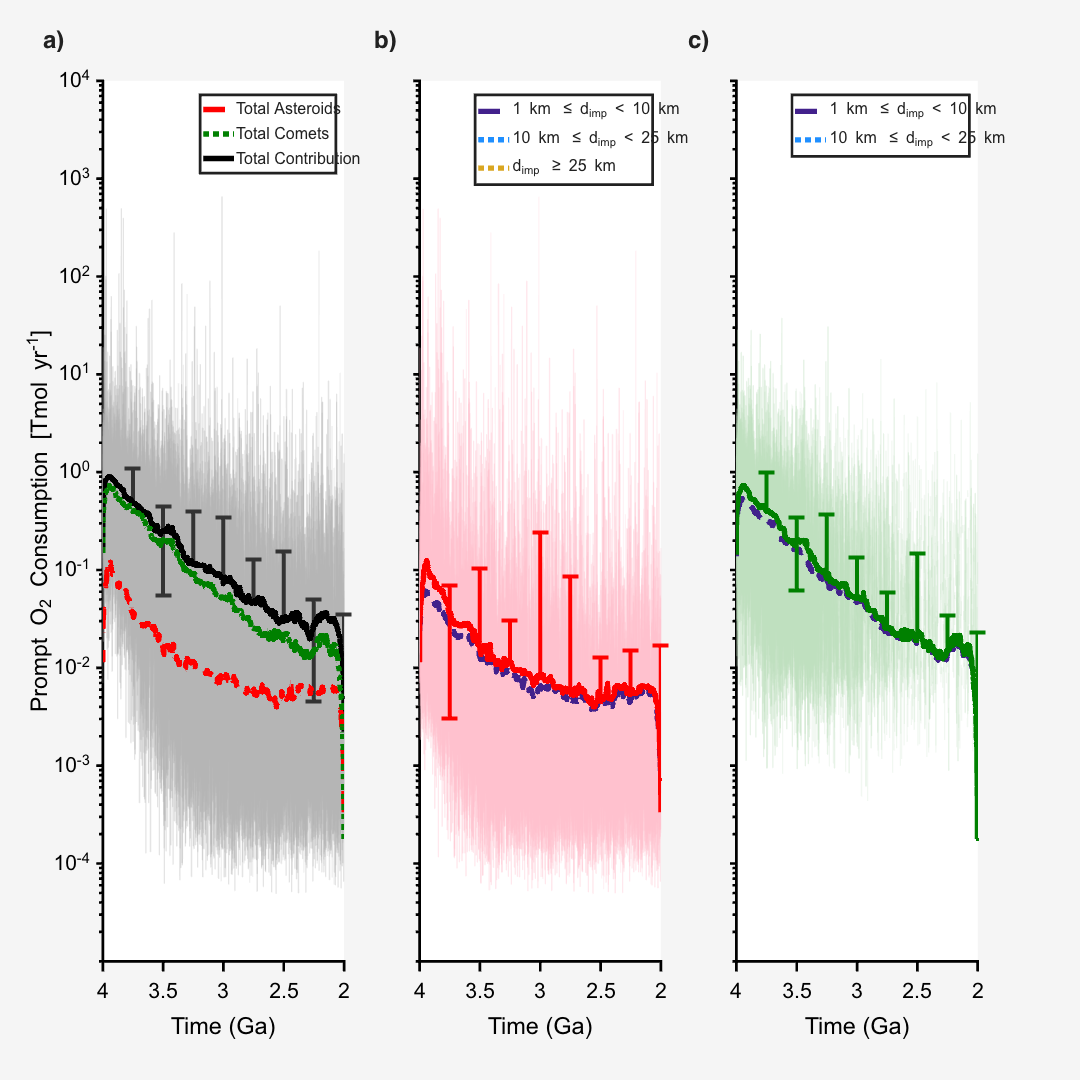


%% =======================================================================
% FIGURE S3 – Prompt Atmospheric O₂ Consumption from Asteroids and Comets
% Purpose:
%   - Load simulated oxygen consumption datasets for asteroid and comet impacts
%   - Apply smoothing, compute ensemble statistics, and generate a 3-panel plot:
%       (A) Asteroids only — total and size-bin contributions
%       (B) Comets only — total and size-bin contributions
%       (C) Combined total (asteroids + comets) with individual totals overlaid
%   - Show ensemble variability, smoothed means, and standard deviation error bars
%   - Time axis in Ga (billions of years ago), reversed for geological convention
% =======================================================================

fname = sprintf("post_proc_output/impact_count_1_10_25_%d_sims.mat", sim_count);
load(fname);

window_size   = 100;   % 101 Myr smoothing window for movmedian
interval      = 250;   % stride for sparse error-bar x positions

idx = 1:interval:length(t_Ma);

%% --- Data containers ---
asteroid_data = {
    asteroids_1_to_10_km_O2_cons, ...
    asteroids_10_to_25_km_O2_cons, ...
    asteroids_gt_25_km_O2_cons ...
};

comet_data = {
    comets_1_to_10_km_O2_cons, ...
    comets_10_to_25_km_O2_cons ...
};

%% --- Colors ---
purple = [0.26 0.13 0.55];
blue   = [0.12 0.56 1.00];
gold   = [0.85 0.65 0.13];

fade        = @(c, a) (1 - a) * c + a * [1 1 1];
purple_faint = fade(purple, 0.1);
blue_faint   = fade(blue,   0.1);
gold_faint   = fade(gold,   0.1);

%% --- Figure + layout ---
figure('Units','pixels','Position',[100,100,1400,1400]);
tl = tiledlayout(1,3,'TileSpacing','loose','Padding','loose');

line_thickness = 4;

% (A) ASTEROIDS ONLY  — middle panel
nexttile(2); hold on;

% Ensemble overlay from total asteroid O2 consumption
ast_total = asteroid_data{1} + asteroid_data{2} + asteroid_data{3};
seed_idx  = randperm(size(ast_total, 2), ensembles_to_use);
plot(t_Ga, ast_total(:, seed_idx), 'Color', [1 0.75 0.8 0.2], 'LineWidth', 1);

% >25 km (gold, dotted)
m_gt25 = movmedian(mean(asteroid_data{3}, 2), window_size);
h3 = plot(t_Ga, m_gt25, 'Color', gold,   'LineWidth', line_thickness, 'LineStyle', ':');

% 10–25 km (blue, dotted)
m_10_25 = movmedian(mean(asteroid_data{2}, 2), window_size);
h2 = plot(t_Ga, m_10_25, 'Color', blue,   'LineWidth', line_thickness, 'LineStyle', ':');

% 1–10 km (purple, dashed)
m_1_10 = movmedian(mean(asteroid_data{1}, 2), window_size);
h1 = plot(t_Ga, m_1_10, 'Color', purple, 'LineWidth', line_thickness, 'LineStyle', '--');

% Total (red) with classic std error bars
total_mean_asteroid = movmedian(mean(ast_total, 2), window_size);
total_std_asteroid  = std(ast_total, 0, 2);

plot(t_Ga, total_mean_asteroid, 'Color', 'r', 'LineWidth', line_thickness);
errorbar(t_Ga(idx), total_mean_asteroid(idx), total_std_asteroid(idx), ...
    '.', 'Color', 'r', 'CapSize', 12, 'LineStyle', 'none', 'LineWidth', 3, 'HandleVisibility', 'off');

legend([h1 h2 h3], ...
    '1 km \leq d_{imp} < 10 km', ...
    '10 km \leq d_{imp} < 25 km', ...
    'd_{imp} \geq 25 km', ...
    'Location', 'northeast', 'FontSize', 12);

set(gca,'XDir','reverse','YScale','log', ...
    'FontName','Arial','FontSize',16,'TickDir','out', ...
    'XColor','k','YColor','k','LineWidth',2, 'YTickLabel',[]);
xlim([2,4]); ylim([1E-5,1E4]);
xlabel('Time (Ga)');

hold off;

% (B) COMETS ONLY — right panel
nexttile(3); hold on;

% Ensemble overlay from total comet O2 consumption
com_total = comet_data{1} + comet_data{2};
seed_idx  = randperm(size(com_total, 2), ensembles_to_use);
plot(t_Ga, com_total(:, seed_idx), 'Color', [0.74 0.87 0.74 0.2], 'LineWidth', 1);

% 10–25 km (blue, dotted)
mc_10_25 = movmedian(mean(comet_data{2}, 2), window_size);
hC2 = plot(t_Ga, mc_10_25, 'Color', blue, 'LineWidth', line_thickness, 'LineStyle', ':');

% 1–10 km (purple, dashed)
mc_1_10 = movmedian(mean(comet_data{1}, 2), window_size);
hC1 = plot(t_Ga, mc_1_10, 'Color', purple, 'LineWidth', line_thickness, 'LineStyle', '--');

% Total (green) with classic std error bars
total_mean_comet = movmedian(mean(com_total, 2), window_size);
total_std_comet  = std(com_total, 0, 2);

errorbar(t_Ga(idx), total_mean_comet(idx), total_std_comet(idx), ...
    '.', 'Color', [0 0.5 0], 'CapSize', 12, 'LineStyle', 'none', 'LineWidth', 3);
plot(t_Ga, total_mean_comet, 'Color', [0 0.5 0], 'LineWidth', line_thickness, 'LineStyle', '-');

legend([hC1 hC2], ...
    '1 km \leq d_{imp} < 10 km', ...
    '10 km \leq d_{imp} < 25 km', ...
    'Location', 'northeast', 'FontSize', 12);

set(gca,'XDir','reverse','YScale','log', ...
    'FontName','Arial','FontSize',16,'TickDir','out', ...
    'XColor','k','YColor','k','LineWidth',2, 'YTickLabel',[]);
xlim([2,4]); ylim([1E-5,1E4]);
xlabel('Time (Ga)');

hold off;

% (C) TOTAL (ASTEROIDS + COMETS) — left panel
nexttile(1); hold on;

% Ensemble overlay from total asteroid and comet O2 consumption
tot_all = ast_total + com_total;
seed_idx = randperm(size(tot_all, 2), ensembles_to_use);
plot(t_Ga, tot_all(:, seed_idx), 'Color', [0.7 0.7 0.7 0.2], 'LineWidth', 1);

tot_mean = movmedian(mean(tot_all, 2), window_size);
tot_std  = std(tot_all, 0, 2);

% Total (black) with classic std error bars
errorbar(t_Ga(idx), tot_mean(idx), tot_std(idx), ...
    '.', 'Color', [0.2 0.2 0.2 0.3], 'CapSize', 12, 'LineStyle', 'none', 'LineWidth', 3);
h_total = plot(t_Ga, tot_mean, 'Color', 'k', 'LineWidth', line_thickness, 'LineStyle', '-');

% Overlay totals from asteroid and comet panels
h_total_asteroid = plot(t_Ga, total_mean_asteroid, 'Color', 'r',       'LineWidth', line_thickness, 'LineStyle', '--');
h_total_comet    = plot(t_Ga, total_mean_comet,    'Color', [0 0.5 0], 'LineWidth', line_thickness, 'LineStyle', ':');

legend([h_total_asteroid, h_total_comet, h_total], ...
       {'Total Asteroids', ...
        'Total Comets', ...
        'Total Contribution'}, ...
       'Location', 'northeast', 'FontSize', 12);

set(gca,'XDir','reverse','YScale','log', ...
    'FontName','Arial','FontSize',16,'TickDir','out', ...
    'XColor','k','YColor','k','LineWidth',2);
xlim([2,4]); ylim([1E-5,1E4]);
xlabel('Time (Ga)');
ylabel('Prompt O_2 Consumption [Tmol yr^{-1}]');

text(4.5, 2.75E4, 'a)', 'FontSize', 18, 'FontWeight', 'bold');  
text(1.75, 2.75E4, 'b)', 'FontSize', 18, 'FontWeight', 'bold');  
text(-0.85, 2.75E4, 'c)', 'FontSize', 18, 'FontWeight', 'bold'); 

hold off;

% Generate plots
set(gcf,'Visible','on');
exportgraphics(gcf, 'plots/figure_s3.pdf', 'ContentType', plot_output_type, 'Resolution', resolution_scale);

### FIGURE S4 – Atmospheric O₂ Evolution and Suppression Probability

%% =======================================================================
% FIGURE S4 – Atmospheric O₂ Evolution and Suppression Probability
% Purpose:
%   - Load simulation results of atmospheric O₂ consumption and sinks
%   - Compute median and 95% confidence intervals from ensemble simulations
%   - Incorporate external sink estimates (Catling et al., 2014) and 
%     reduced impactor sink bounds (Marchi et al., 2021)
%   - Create a 2-panel figure:
%       (a) O₂ evolution over geological time with shaded confidence intervals
%           and comparison to volcanic/metamorphic sink estimates
%       (b) Probability of O₂ suppression exceeding given thresholds
%   - Apply Great Oxidation Event (GOE) shading for reference
%   - Display time in Ga (billions of years ago), reversed to match
%     geological convention
% =======================================================================


fname = sprintf('post_proc_output/impact_O2_loss_response_%d_sims.mat', sim_count);
load(fname);

p_ox = 15;  % Reference normalization constant for sinks

% Prepare simulation outputs
t_all = x(:);                % Time vector in Ma
y_all = total_gaussian(:);   % Summed O2 values across all seeds

% Preallocate arrays for median and confidence intervals (95%)
CI_lower     = zeros(2001, 1);   % 2.5th percentile
CI_upper     = zeros(2001, 1);   % 97.5th percentile
median_curve = zeros(2001, 1);   % Median curve

% Loop over each time index to compute statistics across seeds
for i = 1:2001
    data = gaussian_by_seed(i, :);    % Values for all seeds at time i
    median_curve(i) = median(data);
    CI_lower(i)     = prctile(data, 2.5);
    CI_upper(i)     = prctile(data, 97.5);
end

% Load and clean Marchi et al. (2021) dataset
marchi_data = readtable("datasets/marchi_dataset_2021.csv", 'VariableNamingRule', 'preserve');

% Extract numeric arrays from table columns
marchi_time_upper_bound = double(marchi_data{:,1});
marchi_data_upper_bound = double(marchi_data{:,2});
marchi_time_lower_bound = double(marchi_data{:,3});
marchi_data_lower_bound = double(marchi_data{:,4});

% Remove NaNs or Infs
valid_upper = isfinite(marchi_time_upper_bound) & isfinite(marchi_data_upper_bound);
valid_lower = isfinite(marchi_time_lower_bound) & isfinite(marchi_data_lower_bound);

marchi_time_upper_clean = marchi_time_upper_bound(valid_upper);
marchi_data_upper_clean = marchi_data_upper_bound(valid_upper);
marchi_time_lower_clean = marchi_time_lower_bound(valid_lower);
marchi_data_lower_clean = marchi_data_lower_bound(valid_lower);

% Interpolation axis in Ga (2.5–4 Ga range)
t_interp = linspace(2.5, 4, 1501)';

% Interpolate upper/lower bounds to match axis
marchi_data_upper_bound_interp = interp1(marchi_time_upper_clean, marchi_data_upper_clean, t_interp, 'linear', 'extrap');
marchi_data_lower_bound_interp = interp1(marchi_time_lower_clean, marchi_data_lower_clean, t_interp, 'linear', 'extrap');


% Figure setup — two panels
figure('Units', 'inches', 'Position', [1, 1, 11, 6], 'PaperPositionMode', 'auto');
tiledlayout(1,2, 'Padding', 'compact', 'TileSpacing', 'loose');


% (a) Time series: O2 evolution with confidence intervals and sinks
nexttile;

% Smooth curves for display
CI_lower_smooth  = smoothdata(CI_lower, 'movmean', 25);
CI_upper_smooth  = smoothdata(CI_upper, 'movmean', 25);
median_smooth    = smoothdata(median_curve, 'movmean', 25);

% Clip lower bound to avoid plotting below threshold
CI_lower_clipped = max(CI_lower_smooth, 1e-5);

% Time axis in Ga
t_Ga = t_all / 1000;

% Prepare shaded 95% CI region
fill_area_x = [t_Ga; flipud(t_Ga)];
fill_area_y = [CI_lower_clipped; flipud(CI_upper_smooth)];
h_band = fill(fill_area_x, fill_area_y, [0.8 0.9 1], 'EdgeColor', 'none', 'FaceAlpha', 0.35);
hold on;

% X/Y limits
xlim([2, 4]);
ylim([1E-4, 1E4]);


% Overlay spaghetti plots (subset of seeds)
light_orange = [1, 0.85, 0.4, 0.85];
if sim_count < 50
    % --- Plot all seeds ---
    for i = 1:sim_count
        plot(t_Ga, gaussian_by_seed(:,i), 'Color', light_orange, ...
             'LineWidth', 0.75, 'HandleVisibility', 'off');
    end

elseif sim_count <= 100
    % --- Plot every 10th seed, plus the last ---
    for i = 1:10:sim_count
        plot(t_Ga, gaussian_by_seed(:,i), 'Color', light_orange, ...
             'LineWidth', 0.75, 'HandleVisibility', 'off');
    end
    plot(t_Ga, gaussian_by_seed(:,sim_count), 'Color', light_orange, ...
         'LineWidth', 0.75);

else
    % --- Plot every 100th seed, plus the last ---
    for i = 1:100:sim_count
        plot(t_Ga, gaussian_by_seed(:,i), 'Color', light_orange, ...
             'LineWidth', 0.75, 'HandleVisibility', 'off');
    end
    plot(t_Ga, gaussian_by_seed(:,sim_count), 'Color', light_orange, ...
         'LineWidth', 0.75);
end


% Median curve
h_median = plot(t_Ga, median_smooth, '-', 'LineWidth', 5, 'Color', [0.1, 0.1, 0.6]);

% CI boundary lines
plot(t_Ga, CI_lower_clipped, ':', 'Color', [0.4 0.4 0.4], 'LineWidth', 1, 'HandleVisibility','off');
plot(t_Ga, CI_upper_smooth, ':', 'Color', [0.4 0.4 0.4], 'LineWidth', 1, 'HandleVisibility','off');

% Marchi et al. shaded region
t_fill = [t_interp; flipud(t_interp)];
y_fill = [marchi_data_lower_bound_interp; flipud(marchi_data_upper_bound_interp)];
h_marchi = fill(t_fill, y_fill, [1, 0.7, 0.7], 'EdgeColor', 'none', 'FaceAlpha', 0.5);

% Other sink datasets
csv_read = readtable("datasets/catling_et_al_2014_sinks.csv");
data = table2array(csv_read);

% Volcanic Sink (Catling et al., 2014)
h_volcanic = plot(data(:,1), data(:,2)/p_ox, 'LineWidth', 4, 'LineStyle', ':', 'Color', [0.0, 0.5, 0.0]);

% Metamorphic Sink (Catling et al., 2014)
h_metamorphic = plot(data(:,5), data(:,6)/p_ox, 'LineWidth', 4, 'LineStyle', '--', 'Color', [0.5, 0.2, 0.5]);

% Great Oxidation Event (GOE) shaded region
goe_start = 2.45;
goe_end   = 2.30;
yl = ylim;
fill([goe_start goe_end goe_end goe_start], [yl(1) yl(1) yl(2) yl(2)], ...
     [0.75 1 0.75], 'EdgeColor', 'none', 'FaceAlpha', 0.5, 'HandleVisibility', 'off');
text(2.375, 0.000000025 * yl(2), 'GOE', 'HorizontalAlignment', 'center', ...
    'Color', [0 0 0], 'FontWeight', 'bold', 'FontSize', 10);


% Legend
legend([h_median, h_band, h_volcanic, h_metamorphic, h_marchi], ...
  'Median (Impact Melt Degassing)', ...
  '95% CI (Impact Melt Degassing)', ...
  'Volcanic Sink (Catling et al., 2014)', ...
  'Metamorphic Sink (Catling et al., 2014)', ...
  'Reduced Impactor Sink (Marchi et al., 2021)', ...
  'FontSize', 10, 'Location', 'northeast');

% Axes styling
set(gca, 'FontName', 'Arial', 'FontSize', 16, 'TickDir', 'out', ...
    'XColor', 'k', 'YColor', 'k', 'LineWidth', 2, ...
    'XTick', [2 2.5 3 3.5 4], 'YTick', [1E-4 1E-2 1E0 1E2 1E4], ...
    'XDir', 'reverse', 'YScale', 'log');

xlabel('Time (Ga)');
ylabel({'Normalized Atm. O_2 (S_{ox}/P_{ox})'});


% (b) Probability of suppression levels over time
nexttile;

[n_time, n_seeds] = size(gaussian_by_seed);

% Fraction of simulations in each suppression category
suppression_instant_low  = sum((gaussian_by_seed > 1)   & (gaussian_by_seed <= 10),2) / n_seeds;
suppression_instant_mid  = sum((gaussian_by_seed > 10)  & (gaussian_by_seed <= 100),2) / n_seeds;
suppression_instant_high = sum(gaussian_by_seed > 100,2) / n_seeds;
suppression_combined     = sum(gaussian_by_seed > 1,2) / n_seeds;

% Plot each suppression category
plot(t_Ga, suppression_instant_low,  'LineWidth', 2, 'Color', [0, 0.5, 0],    'LineStyle', '--'); hold on;
plot(t_Ga, suppression_instant_mid,  'LineWidth', 2, 'Color', [0.80, 0.47, 0], 'LineStyle', ':'); hold on;
plot(t_Ga, suppression_instant_high, 'LineWidth', 2, 'Color', [0.35, 0.7, 0.9],'LineStyle', '-.'); hold on;
plot(t_Ga, suppression_combined,     'LineWidth', 2, 'Color', [0, 0, 0],       'LineStyle', '-'); hold on;

% Legend
legend( ...
  '1 < S_{ox}/P_{ox} \leq 10', ...
  '10 < S_{ox}/P_{ox} \leq 100', ...
  'S_{ox}/P_{ox} > 100', ...
  'S_{ox}/P_{ox} > 1', ...
  'FontSize', 10, 'Interpreter', 'tex', 'Location', 'northeast');

% GOE shading
fill([goe_start goe_end goe_end goe_start], [0 0 100 100], ...
     [0.75 1 0.75], 'EdgeColor', 'none', 'FaceAlpha', 0.3, 'HandleVisibility', 'off');
text(2.375, 0.015, 'GOE', 'HorizontalAlignment', 'center', 'FontWeight', 'bold', 'FontSize', 10);

% Axes styling
set(gca, 'FontName', 'Arial', 'FontSize', 16, 'TickDir', 'out', ...
    'XDir', 'reverse', 'XColor', 'k', 'YColor', 'k', 'LineWidth', 2, ...
    'XTick', [2 2.5 3 3.5 4], 'YTick', 0:0.1:0.8);
xlim([2, 4]);
ylim([0, 0.3]);
xlabel('Time (Ga)');
ylabel('Probability of S_{ox}/P_{ox}');
grid on;

% Panel labels
annotation('textbox', [0.00, 0.95, 0.03, 0.03], 'String', '(a)', ...
           'FontSize', 16, 'FontWeight', 'bold', 'EdgeColor', 'none');
annotation('textbox', [0.48, 0.95, 0.03, 0.03], 'String', '(b)', ...
           'FontSize', 16, 'FontWeight', 'bold', 'EdgeColor', 'none');

% Generate plots
set(gcf, 'Visible', 'on');
exportgraphics(gcf, 'plots/figure_s4.pdf', 'ContentType', plot_output_type, 'Resolution', resolution_scale);